# Augmented Reality Using AprilTag Markers

This example shows how to use marker-based augmented reality to render virtual content into a scene. 

## Overview

Augmented reality (AR) enables the creation of novel applications by enhancing the real-world scene through naturally blending real and virtual content. For example, an augmented reality application can add virtual rulers to enable a user to make measurements directly from image data. Implementing an augmented reality system requires using computer vision techniques to understand the scene geometry so that virtual content can be added to a scene with the proper perspective and scale. 

A common approach to determining scene geometry is to use a calibrated camera to detect a known fiducial marker, such as an AprilTag. The benefit of using fiducial markers is that they are designed to be detected under a variety of imaging conditions and viewpoints and can be used to produce accurate camera pose estimates. Accurate pose estimates are critical for producing a seamless AR experience that does not jitter as the camera moves through the scene.

In this example, a calibrated camera is used to detect and track an AprilTag marker placed on top of a table. The AprilTag pose is estimated as the camera moves through the scene and this information is used to project a virtual cuboid on top of the AprilTag. The workflow shown in this example highlights the fundamental computer vision techniques used in many AR applications. 

## Load Video 

Download the video file into a temporary directory.

videoFilename = downloadVideo(tempdir);

Load the video into which AR content is to be added and read the first frame.

reader = VideoReader(videoFilename);
I = readFrame(reader);

Display the first frame.

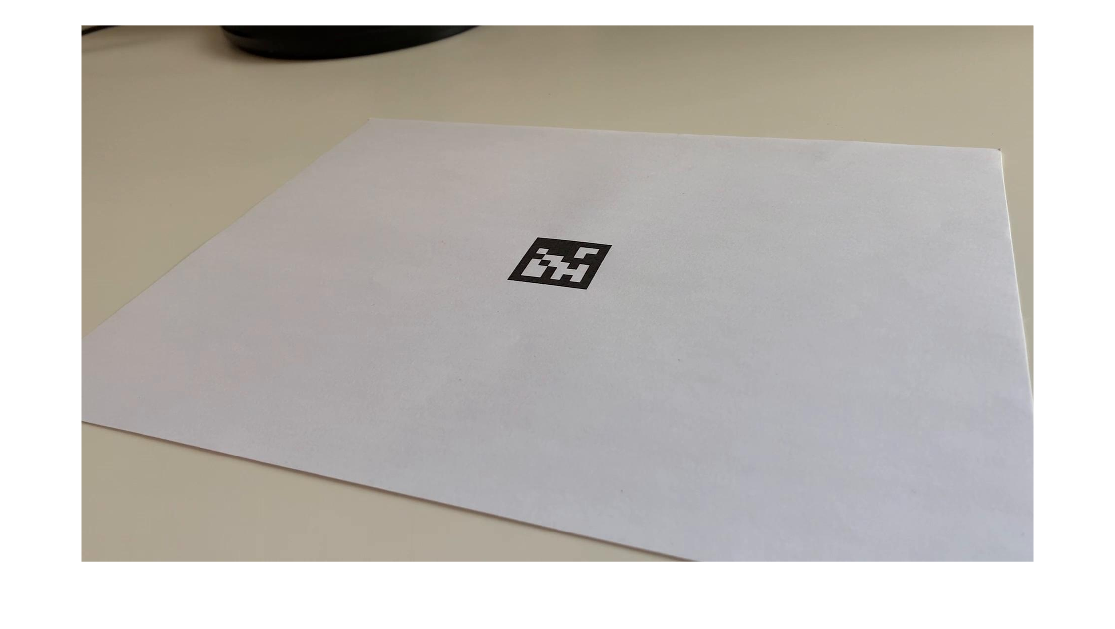

figure
imshow(I)

## Load Camera Intrinsics

AR and VR applications require a calibrated camera to define the position of the camera in the world. Load the camera intrinsics estimated using the [Camera Calibrator](docid:vision_ug#btxr8c_-1) app.

data = load("arCameraCalibrationParameters.mat");
intrinsics = data.cameraParams.Intrinsics;

## Estimate AprilTag Pose

The [`readAprilTag`](docid:vision_ref#mw_cbc70d14-d88a-4c73-9173-e86373a2a524) function can be used to detect and estimate the pose of multiple AprilTags. To estimate the pose, the function requires the camera intrinsics and the size of the AprilTag. Specify the size of the AprilTag in millimeters to match the units used during camera calibration. Because the AprilTag is square, measuring the length of one side is sufficient. It is important to measure the size accurately to produce an accurate pose estimate. 

tagSize = 27.7813; % in mm

To make the AprilTag detection faster and reduce false detections, specify the AprilTag family. `readAprilTag` supports a wide range of AprilTags.

tagFamily = "tag36h11";

Estimate the AprilTag pose.

[~, ~, tagPose] = readAprilTag(I, tagFamily, intrinsics, tagSize);

The pose of the AprilTag defines the world coordinate system used in this example. The center of the AprilTag is the origin. The X-Y plane is defined by the planar surface on which the AprilTag sits and the Z axis points into the tag. Use `helperInsertXYZAxes` to visualize the X, Y, and Z world axes on the AprilTag to get a better understanding of the world coordinate system. The X, Y, and Z axes are represented by red, green, and blue lines, respectively.

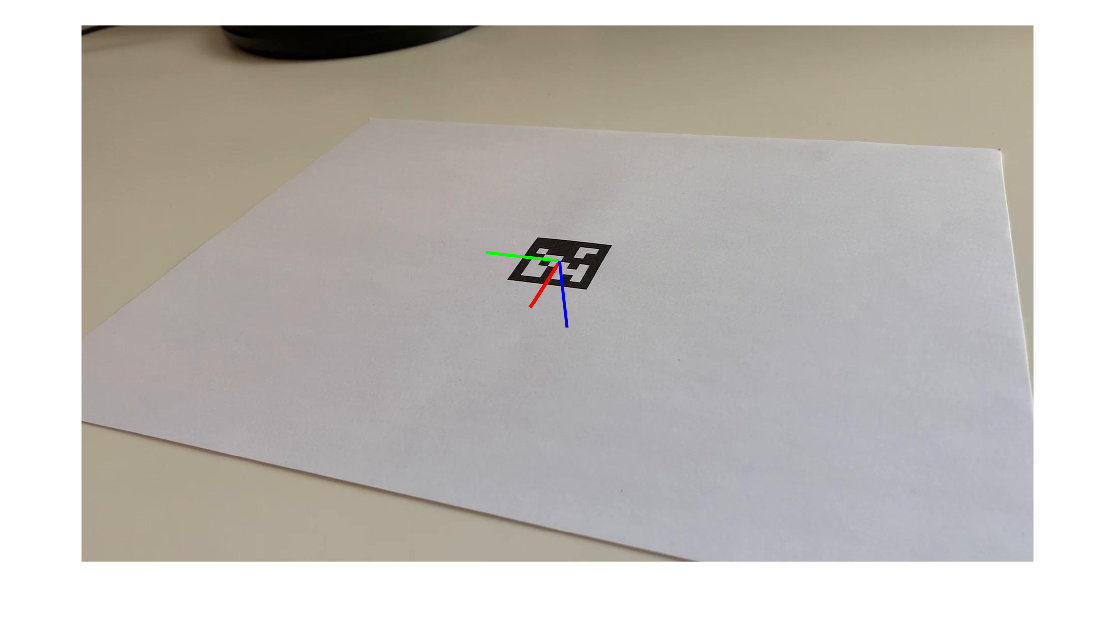

annotatedImage = helperInsertXYZAxes(I, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

By convention, the `readAprilTag` function returns the AprilTag pose such that the z-axis points into the AprilTag. For this example, it is more intuitive to have the z-axis point out of the tag such that virtual objects that sit on top of the AprilTag can be defined to have positive height values. Apply a rotation to the estimated tag pose that rotates the y-axis by 180 degrees to flip the z-axis. 

rotationAngles = [0 180 0];
tform = rigidtform3d(rotationAngles, [0 0 0]);
updatedR = tagPose.R * tform.R;
tagPose = rigidtform3d(updatedR, tagPose.Translation);

Display the updated world coordinate axes. 

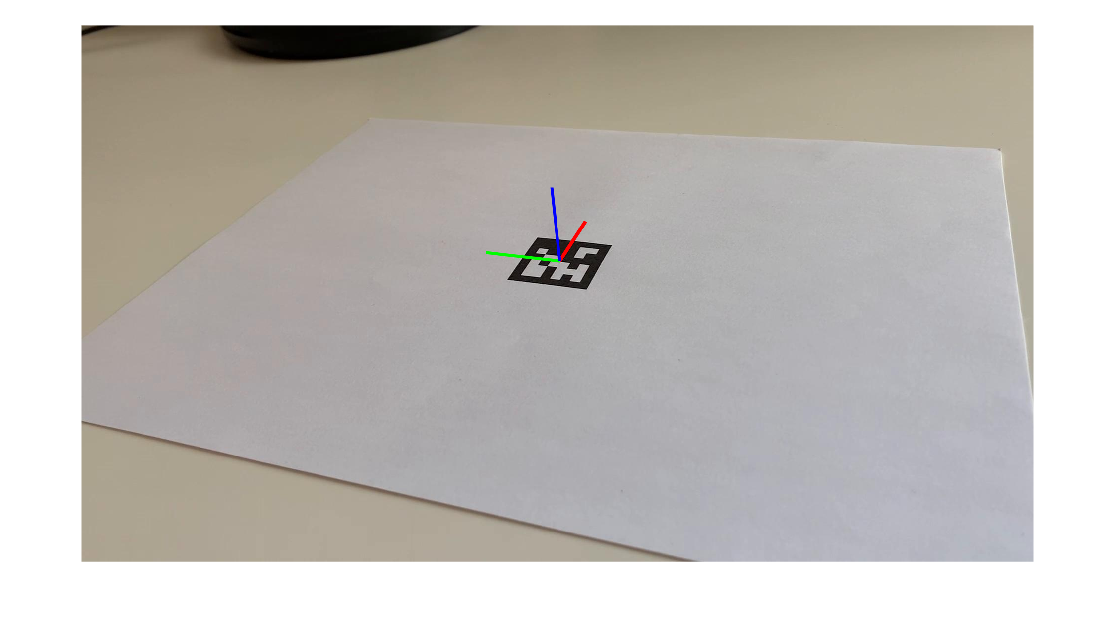

annotatedImage = helperInsertXYZAxes(I, tagPose, intrinsics, tagSize);
figure
imshow(annotatedImage)

## Define Virtual Content

Define a 3-D cuboid to project onto the top of the AprilTag. The cube is centered on the AprilTag and defined to have the same size as the tag. 

[cubeWidth, cubeHeight, cubeDepth] = deal(tagSize);

vertices = [ cubeWidth/2 -cubeHeight/2; 
             cubeWidth/2  cubeHeight/2;
            -cubeWidth/2  cubeHeight/2;
            -cubeWidth/2 -cubeHeight/2 ];

cuboidVertices = [vertices zeros(4,1);
                  vertices (cubeDepth)*ones(4,1)];

## Add Virtual Content to Image

Use [`world2img`](docid:vision_ref#mw_69af89ba-6463-4387-a15c-7c8e1fa5579f) to project the virtual cuboid vertices into the image coordinate system. 

projectedVertices = world2img(cuboidVertices, tagPose, intrinsics);

Use [`insertShape`](docid:vision_ref#btppvxj-1) to augment the image with the virtual content.

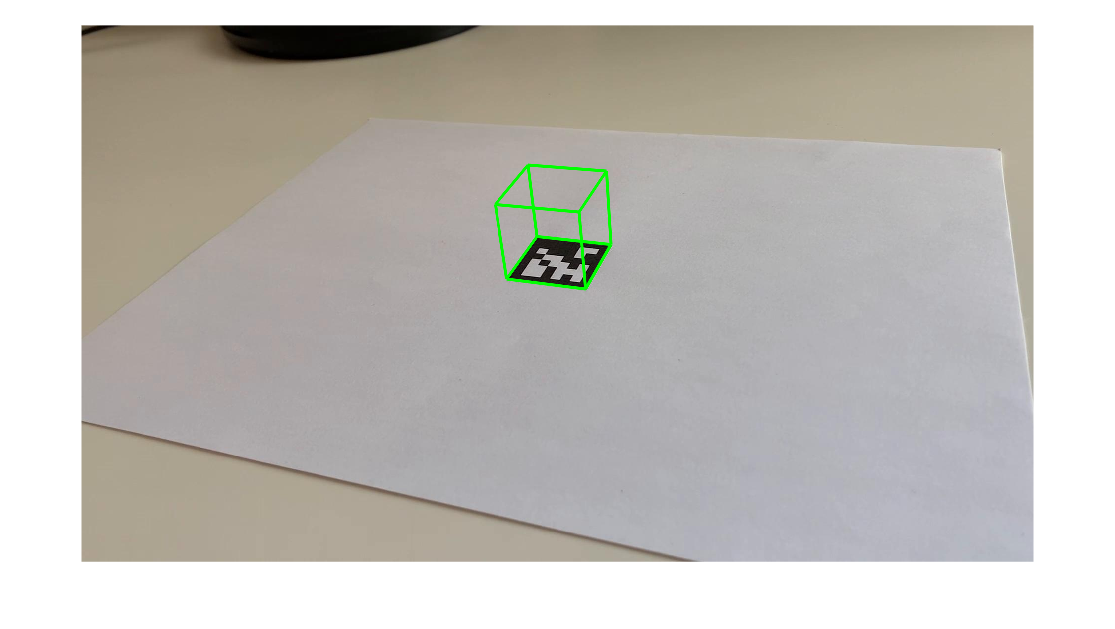

figure
augmentedImage = insertShape(I, "projected-cuboid", projectedVertices, ...
    ShapeColor="green", LineWidth=6);
imshow(augmentedImage)

## Visualize Camera Pose in 3-D

Use the estimated AprilTag pose and camera intrinsics to create a 3-D virtual representation of the scene corresponding to the image shown above. This virtual representation is useful for visualizing the camera trajectory and debugging AR applications. To start, add the cuboid defined above to the virtual scene with `helperShowVirtualCuboid`, which is a function listed at the end of this example.

figure
ax = helperShowVirtualCuboid(cuboidVertices);

Next, use [`pose2extr`](docid:vision_ref#mw_4d90cc38-ac81-4889-930f-265305142218) to convert the tag pose to the camera extrinsics, which represent the camera orientation and location in world coordinates.

camExtrinsics = pose2extr(tagPose);

Finally, use [`plotCamera`](docid:vision_ref#bup3vo1-1) to visualize the camera in 3-D. 

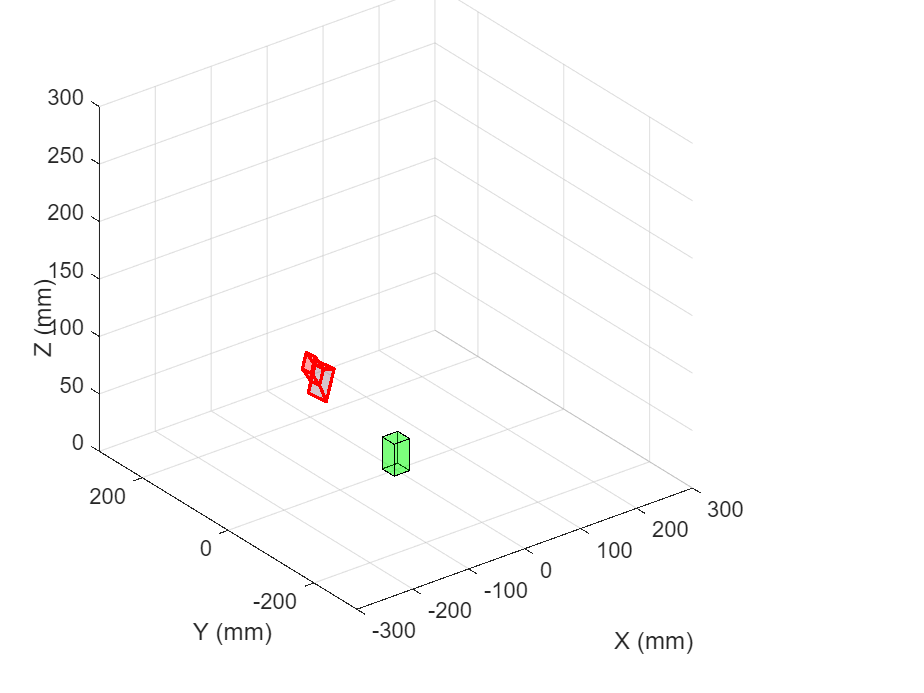

hold on
cam = plotCamera(AbsolutePose=camExtrinsics, Size=15, Parent=ax);

The next section of this example shows how to update the camera position to visualize the trajectory as the camera moves through the scene. 

## Add Virtual Content to Video and Visualize Camera Trajectory

Repeat the steps above on the remaining video frames. 

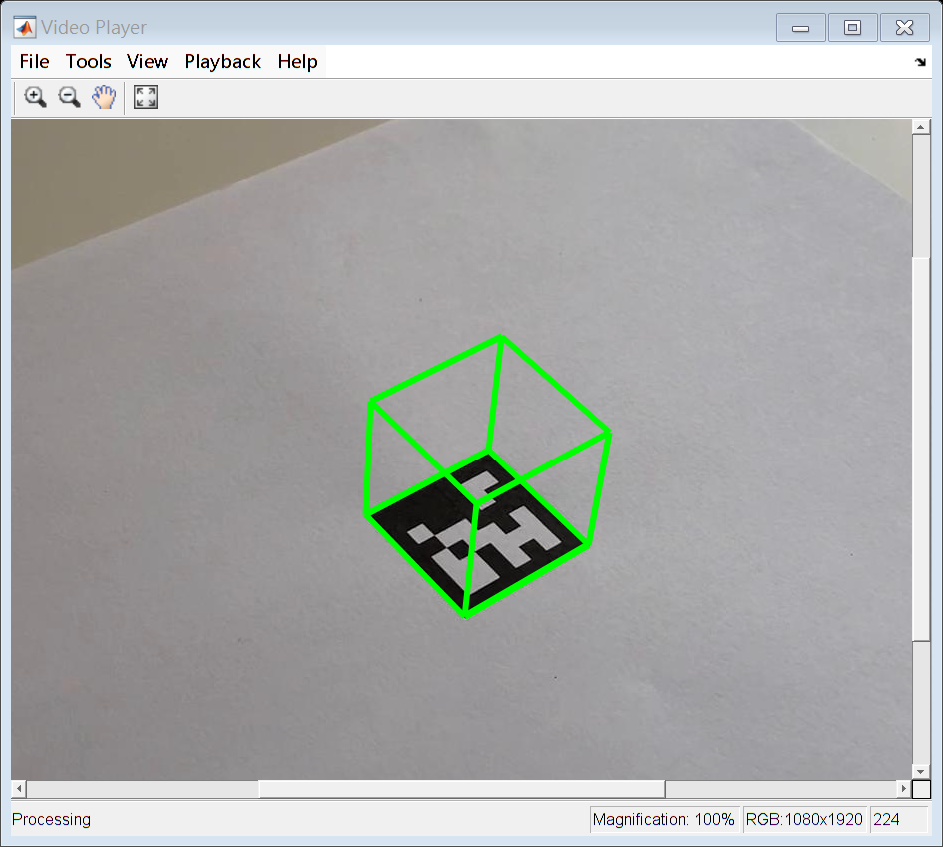

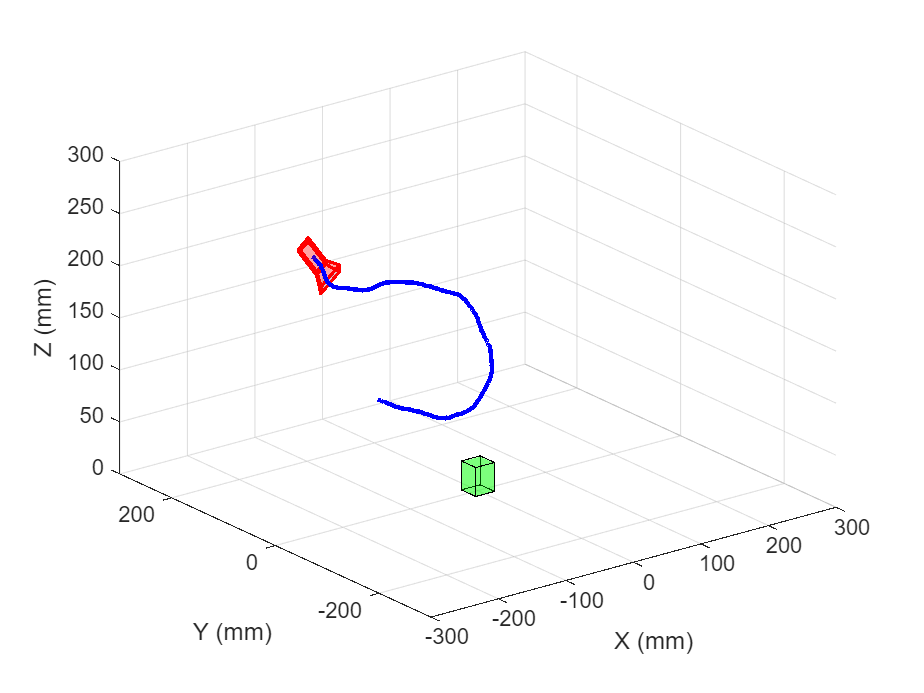

% Create a video player to display video content.
player = vision.VideoPlayer();

% Create an animated line to display camera trajectory.
camTrajectory = animatedline(ax, ...
    camExtrinsics.Translation(1),...
    camExtrinsics.Translation(2),...
    camExtrinsics.Translation(3),...
    Color="blue", ...
    LineWidth=2);
% Loop over remaining video frames.
while hasFrame(reader)

    % Read next video frame.
    I = readFrame(reader);

    % Estimate AprilTag pose.
    [~, ~, tagPose] = readAprilTag(I, tagFamily, intrinsics, tagSize);

    % Update the tag pose to have z-axis pointing out of the tag.
    tagPose = rigidtform3d(tagPose.A*tform.A);

    % Project cuboid vertices from the world to image.
    projectedVertices = world2img(cuboidVertices, tagPose, intrinsics);
    
    % Insert cuboid into video frame. 
    augmentedImage = insertShape(I, "projected-cuboid", projectedVertices, ...
        ShapeColor="green", LineWidth=6);

    % Display the augmented video frame.
    player(augmentedImage)  

    % Update the camera position in the virtual scene.
    camExtrinsics = pose2extr(tagPose);
    cam.AbsolutePose = camExtrinsics;

    % Update camera trajectory in the virtual scene.
    addpoints(camTrajectory, ...
        camExtrinsics.Translation(1),...
        camExtrinsics.Translation(2),...
        camExtrinsics.Translation(3));

    % Flush the graphics pipeline.
    drawnow limitrate
end

## Summary

This example showcased the fundamental computer vision techniques needed to augment a scene with virtual content using marker-based AR. The techniques shown in this example can be extended to add different types of content to a scene such as images or other 3-D shapes.

## Supporting Functions

### helperInsertXYZAxes - Insert XYZ axes into an image

function J = helperInsertXYZAxes(I, pose, intrinsics, axisLength)

xyzWorld = [0 0 0; axisLength 0 0; 0 axisLength 0; 0 0 axisLength];
xyzImage = worldToImage(intrinsics, pose, xyzWorld);

J = insertShape(I,...
    "Line", [
    xyzImage(1,:) xyzImage(2,:)
    xyzImage(1,:) xyzImage(3,:)
    xyzImage(1,:) xyzImage(4,:)
    ], ...
    ShapeColor=["red";"green";"blue"],...
    LineWidth=7);
end

### helperShowVirtualCuboid - Display a cuboid in a 3-D plot

function ax = helperShowVirtualCuboid(cuboidVertices)

% Create an axes with predefined limits.
ax = axes(XLim=[-300 300], YLim=[-300 300], ZLim=[0 300],...
    XLimMode="manual", YLimMode="manual", ZLimMode="manual");
grid on

% Create a cuboid using patch. Define faces corresponding to
% sets of cuboid vertices.
faces = [1 2 3 4;
         5 6 7 8;
         2 6 7 3;
         1 4 8 5;
         1 2 6 5;
         3 4 8 7];

patch(Faces=faces, Vertices=cuboidVertices, FaceColor="green", FaceAlpha=0.3);

% Add axis labels.
xlabel("X (mm)")
ylabel("Y (mm)")
zlabel("Z (mm)")
view(3)
end

### downloadVideo - Download example video

function videoFilename = downloadVideo(downloadFolder)

url = "https://ssd.mathworks.com/supportfiles/vision/data/arAprilTag.zip";
zipFile = fullfile(downloadFolder,"arAprilTag.zip");

% Download video file.
if ~exist(zipFile, "file")
    websave(zipFile,url)
end

% Unzip video file.
videoFilename = fullfile(downloadFolder,"arAprilTag.avi");
if ~exist(videoFilename, "file")
    unzip(zipFile,downloadFolder);
end
end

*Copyright 2022 The MathWorks, Inc. *